clear; clc; close all;
% simulation settings
DATA_CAST       = 'gpuArray-single';     % set to 'single' or 'gpuArray-single' to speed up computations
RUN_SIMULATION  = true;         % set to false to reload previous results instead of running simulation

% =========================================================================
% DEFINE THE K-WAVE GRID
% =========================================================================
    
% set the size of the perfectly matched layer (PML)
pml_x_size = 40;                % [grid points] *2
pml_y_size = 10;                % [grid points]
pml_z_size = 10;                % [grid points]
            
Nx = 600 - 2 * pml_x_size;      % [grid points] 2048
Ny = 600- 2 * pml_y_size;      % [grid points] 1024
Nz = 600 - 2 * pml_z_size;      % [grid points]
            
% calculate the spacing between the grid points
ratio = 1; % grid per element [grid points] ?
pitch =  0.3e-3;
dx = pitch/ratio;           % [m]
dy = dx;
dz = dx;                        % [m]
x = dx*Nx;                      % [m]
disp(x*1000);

   156



y = dy*Ny;                    % [m]
disp(y*1000);

   174



z = dz*Nz;                      % [m]
disp(z*1000)

   174



% create the k-space grid
kgrid = kWaveGrid(Nx, dx, Ny, dy, Nz, dz);

% =========================================================================
% DEFINE THE MEDIUM PARAMETERS
% =========================================================================
alpha = 0;
cycles= 4.5;
% define the properties of the propagation medium
c0 = 1540;                      % [m/s]
rho0 = 1000;                    % [kg/m^3]
medium.alpha_coeff = alpha;      % [dB/(MHz^y cm)]
medium.alpha_power = 0;

% create the time array
t_end = (Nx * dx) * 2.2 / c0;   % [s]
kgrid.makeTime(c0, [], t_end);

% =========================================================================
% DEFINE THE INPUT SIGNAL
% ========================================================================
% define properties of the input signal
source_strength = 1e6;          % [Pa]
tone_burst_freq = 5e6;        % [Hz]
tone_burst_cycles = cycles; %5 10 15 20  
v = 5;
input_signal_norm = toneBurst(1/kgrid.dt, tone_burst_freq, tone_burst_cycles, 'Envelope', 'Gaussian');
input_signal = (source_strength ./ (c0 * rho0)) .* input_signal_norm;

% =========================================================================
% DEFINE THE ULTRASOUND TRANSDUCER
% =========================================================================
        
% physical properties of the transducer
transducer.number_elements = 8;  	% total number of transducer elements
transducer.element_width = 5;       % width of each element [grid points] 9
transducer.element_length = 100;  	% length of each element [grid points] 166
transducer.element_spacing = 0;  	% spacing (kerf  width) between the elements [grid points] 1
transducer.radius = inf;            % radius of curvature of the transducer [m]
        
% calculate the width of the transducer in grid points
transducer_width = transducer.number_elements * transducer.element_width ...
            + (transducer.number_elements - 1) * transducer.element_spacing;
        
% use this to position the transducer in the middle of the computational grid
transducer.position = round([1, Ny/2 - transducer_width/2, Nz/2 - transducer.element_length/2]);
        
% properties used to derive the beamforming delays
transducer.sound_speed = c0;                    % sound speed [m/s]
transducer.focus_distance = inf;              % focus distance [m]
transducer.elevation_focus_distance = inf;    % focus distance in the elevation plane [m] 0.02
transducer.steering_angle = 0;                  % steering angle [degrees]
        
% apodization
%transducer.transmit_apodization = 'Rectangular';    
%transducer.receive_apodization = 'Rectangular';
        
% define the transducer elements that are currently active
number_active_elements = 8;
transducer.active_elements = ones(transducer.number_elements, 1);
        
% append input signal used to drive the transducer
transducer.input_signal = input_signal;
        
% create the transducer using the defined settings
transducer = kWaveTransducer(kgrid, transducer);
        
% print out transducer properties
transducer.properties;

 
k-Wave Transducer Properties
  transducer position:       [1  270  240]
  transducer width:          12mm (40 grid points)
  number of elements:        8
  number of active elements: 8 (elements 1 to 8)
  element width:             1.5mm (5 grid points)
  element spacing (kerf):    0m (0 grid points)
  element pitch:             1.5mm (5 grid points)
  element length:            30mm (100 grid points)
  sound speed:               1540m/s
  focus distance:             infinite
  elevation focus distance:  infinite
  steering angle:            0 degrees
  steering angle max:        auto degrees


% =========================================================================
% DEFINE THE MEDIUM PROPERTIES
% =========================================================================
        
% define a large image size to move across
% number_scan_lines = 500;
Nx_tot = Nx;
% Ny_tot = Ny + number_scan_lines * transducer.element_width;
Ny_tot=Ny;
Nz_tot = Nz;
        
alpha_coeff_map = alpha;
%% 
medium.sound_speed_ref = 1540;
mask = density_map_ball(Nx,Ny,Nz);

sos = zeros(Nx, Ny, Nz);
dens = zeros(Nx, Ny, Nz);
sos(mask==1) = 1950;
sos(mask==0) = 1540;

density_map(mask==1) = 960;density_map(mask==0) = 1000;


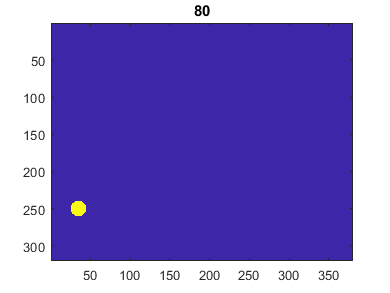

figure;
for i = 1:Nz
    imagesc(squeeze(mask(:,:,i)), [0 1])
    title(i)
    pause(0.01)
end

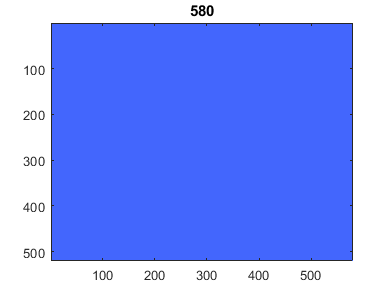

figure;
for i = 1:Nz
    imagesc(squeeze(sos(:,:,i)),[1400 2100])
    title(i)
    pause(0.01)
end

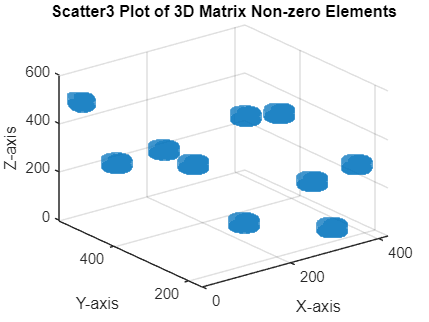

% Get the indices of non-zero elements in the 3D matrix
[xx, yy, zz] = ind2sub(size(mask), find(mask));

% Plot the non-zero elements using scatter3
figure;
scatter3(xx, yy, zz, [],"square");
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Scatter3 Plot of 3D Matrix Non-zero Elements');

% =========================================================================
% RUN THE SIMULATION
% =========================================================================
input_args = {...
'PMLInside', false, 'PMLSize', [pml_x_size, pml_y_size, pml_z_size], ...
'DataCast', DATA_CAST, 'DataRecast', true, 'PlotSim', false};
        
% run the simulation if set to true, otherwise, load previous results from
% disk
% if RUN_SIMULATION
        
% set medium position
medium_position = 1;
number_scan_lines = Ny;
medium.density = density_map;
scan_lines = [];
for scan_line_index = 1:number_scan_lines% number slices
    disp('');
    disp(['Computing scan line PLANE WAVE...']);
    medium.density = density_map(:, medium_position:medium_position + Ny - 1, :);
    % run the simulation
    sensor_data = kspaceFirstOrder3DG(kgrid, medium, transducer, transducer, input_args{:});
    
    % extract the scan line from the sensor data
    scan_lines(scan_line_index, :) = transducer.scan_line(sensor_data);
        
    % update medium position
    medium_position = medium_position + transducer.element_width;
end

Computing scan line PLANE WAVE...


Error using kspaceFirstOrder3DC
The binary file kspaceFirstOrder-CUDA.exe could not be found in C:\Users\cristina\AppData\Roaming\MathWorks\MATLAB Add-Ons\Collections\k-Wave\k-Wave\binaries\. To
use the C++ code, the C++ binaries for your operating system must be downloaded from www.k-wave.org/download.php and placed in the binaries folder.

Error in kspaceFirstOrder3DG (line 69)
sensor_data = kspaceFirstOrder3DC(varargin{:});

%file_out = ['RFgauss_',num2str(source_strength/1000),'kPa_BA9_att0',num2str(alpha(al)*10),'-32'];
%save(file_out,'sensor_data'); clear transducer